# Práctica 1: Reconocimiento de dígitos utilizando el Análisis de las Componentes Principales (**PCA**)

En esta práctica vamos a entrenar un clasificador para reconocer un dígito a partir de una imagen. El problema de reconocer a digítos en una imagen es un problema típico de clasificación. Para resolver estos problemas debemos realizar un proceso de aprendizaje que permita obtener una función, a partir de los ejemplos de entrenamiento disponibles (de los que conocemos su clase), que nos permita clasificar nuevos ejemplos que debamos clasificar en el futuro.

## Conjunto de datos a usar: MNIST

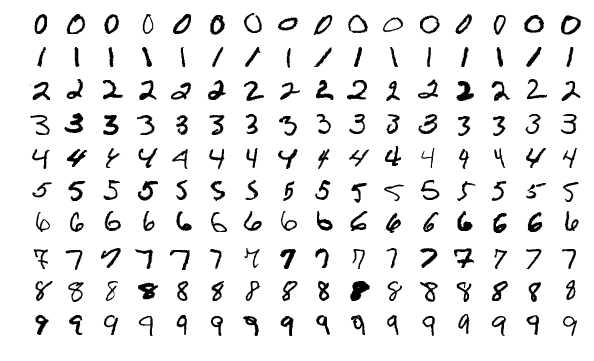

*Tabla 1. Ejemplo de distintas imágenes contenidas en MNIST.*

MNIST es un conjunto de datos de dígitos manuscritos en forma de imagen. Junto con cada imagen, tenemos la etiqueta que indica el número que escribió la persona (las etiquetas están hechas y comprobadas por humanos). En nuestro caso, tenemos tantas clases como distintos números (10 en notación decimal) y tantos ejemplos de entrenamiento como imágenes manuscritas (60,000 imágenes de entrenamiento de y 10,000 para comprobar el rendimiento del clasificador). Cada imagen tiene unas dimensiones de 28x28 pixeles en escala de grises.

Para saber más sobre MNIST: [https://en.wikipedia.org/wiki/MNIST_database](https://en.wikipedia.org/wiki/MNIST_database)

Para **descargar MNIST**: [http://yann.lecun.com/exdb/mnist/](http://yann.lecun.com/exdb/mnist/) (Aunque también debería estar en el material en **miaulario**)

Como ayuda para cargar en MATLAB este conjunto de datos, se da ya el siguiente código. Si no habéis descargado todos los archivos de mialaurio, puede requerir la DeepLearning and Neural Networks toolbox.

trainImagesFile = 'train-images.idx3-ubyte';
trainLabelsFile = 'train-labels.idx1-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';
XTrain = processImagesMNIST(trainImagesFile); %Esta funcion ya os la doy, la podeis encontrar como parte de uno de los ejemplos de MATLAB disponibles online.


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processLabelsMNIST(trainLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


size(XTrain) %28 x 28 (tamano imagen) x 1 (solo hay escala de grises, no pixeles rgb) x 60000 (numero de ejemplos)

ans =           28          28           1       60000


XTrain = XTrain(:,:,:, mod(1:60000, 60000/10) <50);
YTrain = YTrain(mod(1:60000, 60000/10) <50); %Cogemos solo una submuestra

Estas instrucciones nos permiten cargar las imágenes con las que vamos a entrenar. Sin embargo, los clasificadores, como regla de oro, no se evalúan con el mismo conjunto de datos con el que se han entrenado. Generalmente, funcionan muy bien sobre cosas que han visto, pero no son capaces de generalizar tan bien para cosas nuevas. Por eso los conjuntos de datos se dividen en "train", que serán los datos utilizados para entrenar el conjunto de datos, y "test", que nos da el rendimiento real del clasificador. Con los datos de Test NUNCA se entrena. Por ejemplo, en competiciones de clasificación, como las de Kaggle, las etiquetas de los datos de test nunca están disponibles. Generalmente se sigue una proporción de 80% entrenamiento y 20% test, aunque en algounos conjuntos de datos, como el MNIST, las particiones vienen ya dadas.

Para cargar el conjunto de test, el código es el mismo que en el caso anterior:

XTest = processImagesMNIST(testImagesFile);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processLabelsMNIST(testLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


Como hay muchos ejemplos vamos a coger solo 100 imagenes de dos clases distintas (0 y 5). Este código no entra en lo que se os pide. De esas 100 imágenes usaremos 80 para entrenar y 20 para evaluar nuestro rendimiento. Podéis mirar el código si queréis entender bien lo que hace.

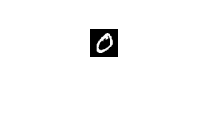

im_lim = 100;
train_lim = int32(im_lim*0.8);
test_lim = int32(im_lim*0.2);
classes = [0, 5];
YTrain = grp2idx(YTrain) - 1;
YTest = grp2idx(YTest) - 1;
[XTrain, YTrain] = filter_classes(XTrain, YTrain, classes);
[XTest, YTest] = filter_classes(XTest, YTest, classes);
XTrain = XTrain(:,:,:,1:train_lim);
YTrain = YTrain(1:train_lim);
XTest = XTest(:,:,:,1:test_lim);
YTest = YTest(1:test_lim);

[YTrain, args_train] = sort(YTrain);
[YTest, args_test] = sort(YTest);
XTrain = XTrain(:,:,:,args_train);
XTest = XTest(:,:,:,args_test);

imshow(XTrain(:,:,:,1));

Una vez hecho esto, ya tenemos cargados los datos como matrices en MATLAB.

**NOTA**: Si has tenido algun problema con las operaciones anteriores, descomenta las siguientes lineas y ejecutalas. Cargaran las particiones de datos generadas tras realizar todos los pasos previos y podras continuar a partir de este punto:

% MNIST_pre_computed = load("MNIST pre_computed partitions.mat");
% XTrain = MNIST_pre_computed.XTrain;
% XTest = MNIST_pre_computed.XTest;
% YTrain = MNIST_pre_computed.YTrain;
% YTest = MNIST_pre_computed.YTest;

## Clasificador propuesto

Existen muchos algoritmos para resolver problemas de clasificación. En esta práctica vamos a utilizar uno de los más sencillos puesto que en la fase de aprendizaje solo tenemos que crear prototipos y en la fase de clasificación solo tenemos que calcular distancias:

- Obtener el prototipo de cada clase: la forma más fácil de obtener el prototipo de una clase es coger todos sus ejemplos (sus imágenes) y calcular la media para cada variable. Es decir, obtendremos una nueva imagen que será la imagen media de todas las de esa clase.

- Para clasificar un ejemplo tenemos que calcular la distancia entre el ejemplo y cada uno de los prototipos. Asignaremos la clase correspondiente al prototipo con el que la distancia sea menor, es decir, el más similar al ejemplo a clasificar.

La Figura 1 muestra este proceso. Este es un problema de 3 clases (c1, c2 y c3) y  2 variables (u1 y u2). Disponemos de 11 ejemplos de entrenamiento, 3 de la clase c2 y 4 de las clases c1 y c3 que están enmarcados dentro de los tres círculos grises. Los prototipos creados para cada clase están representados mediante las cruces rojas. El punto verde es un nuevo ejemplo a clasificar para lo que calcularíamos la distancia entre este punto y cada prototipo. Es comprensible, que dada la ubicación del nuevo ejemplo, será asignado a la clase 2 puesto que su prototipo es el más cercano (el más similar).

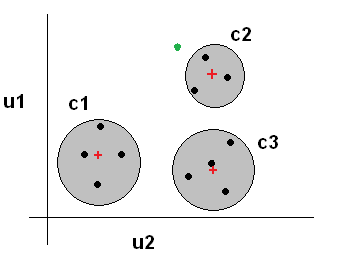

*Figura 1**. Proceso de clasificación tras aplicar el algoritmo PCA, que habrá aprendido el mecanismo para proyectar los ejemplos en las nuevas variables u1 y u2.*

Cuando no existe solapamiento entre los ejemplos de las diferentes clases (los ejemplos de las diferentes clases no se mezclan entre ellos) los prototipos creados están alejados entre ellos y no existen dudas. Sin embargo, si tuviéramos problemas como ruido, atributos redundantes (nos ofrecen la misma información), etc… los prototipos creados podrían no representar bien las características (distribución) del problema. 

Para tratar de afrontar este problema se suele utilizar el análisis de las componentes principales (PCA en inglés) puesto que transforma los datos originales en unos nuevos datos que permiten reflejar mejor las características del problema de forma que facilita la posterior clasificación. Además, el PCA también ofrece la posibilidad de reducir la información guardada para afrontar el problema. Para realizar esta transformación lo que realiza el PCA es un cambio de base (pasa de la base canónica a otra) y obtiene las coordenadas de los datos originales en la nueva base. Estas nuevas coordenadas serán los nuevos atributos del problema.

## PCA: Bases e imágenes

Si hablamos de un espacio definido por 2 atributos (x e y) somos capaces de visualizar fácilmente la situación de cualquier ejemplo que tengamos. Por ejemplo, si nos llega el ejemplo (3, 2) lo visualizamos como se muestra en la Figura 2.

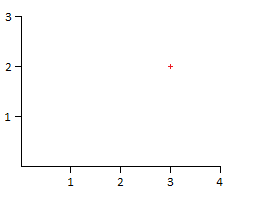

*Figura **2. Representación del punto (3,2) utilizando la base canónica*

Esto es debido a que estamos utilizando la base canónica compuesta por los vectores:

- (1,0) para la componente x.

- (0, 1) para la componente y.

De esta forma el punto (3,2) es el resultado de hacer la siguiente operación: $3*(1, 0) + 2*(0, 1)$.

En nuestro problema, cada ejemplo (foto) tiene tantos atributos como píxeles. Es decir, como las imágenes son de 28x28, van a tener $28*28= 784$ atributos. Si pensamos en una imagen como un vector de 784 elementos (transformamos la foto de matriz a vector) nos damos cuenta que cada píxel sería una coordenada que multiplicaría a su vector correspondiente. Es decir:

- Píxel 1 * (1, 0, …, 0): tendremos 783 ceros después del 1.

- Píxel 2 * (0, 1, 0, …, 0): tendremos 782 ceros después del 1.

- Píxel 3 * (0, 0, 1, 0, …, 0): tendremos 781 ceros después del 1.

- …

- Píxel 784 * (0, …, 0, 1): tendremos 783 ceros antes del 1.

En resumen, la base canónica en este caso está compuesta por 784 vectores de 784 elementos.

Tanto en el caso del ejemplo de 2 atributos como en el caso de las fotos podemos representar cualquier ejemplo (sus coordenadas) en otra base diferente de la canónica.

El algoritmo PCA nos provee un procedimiento para aprender una nueva base en función de los ejemplos de entrada de tal forma que se magnifiquen las diferencias entre los mismos. Como consecuencia, las coordenadas de los ejemplos en la nueva base reflejaran mejor las diferencias entre ellos y facilitarán el proceso de clasificación.

## Implementación

 En esta práctica vamos a implementar el algoritmo PCA para afrontar el problema del reconocimiento de caras. Vamos a dividir este proceso en varias etapas.

### **Etapa 1: Aprendizaje de la nueva base**

Esta etapa está compuesta por 6 pasos:

- Cargar el conjunto de datos inicial. Se debe añadir cada imágen como una columna de una matriz llamada ***R***. Las dimensiones de R son NumeroPixeles x NumeroImagenes. (Nota: asegurate aquí que has normalizado los píxeles al $[0,1]$)

- Calcular la media  por filas de la matriz R y almacenarla en una variable llamada ***media***. Es decir, un vector columna en el que cada elemento i será la media de los elementos de R en la fila i.

- Calcular los vectores con media nula. Es decir, a cada foto (columna de R) se le debe restar el vector media calculado en el paso anterior. Almacenar cada vector obtenido en la resta en una columna de una matriz llamada ***A***. Las dimensiones de A son iguales a las de R.

- Calcular la matriz de correlación ***C***. Para ello hay que multiplicar la matriz A transpuesta por la matriz A. La matriz C es una matriz cuadrada compuesta por NumeroFotos x NumeroFotos elementos.

NOTA: este punto es debido a que vamos a aplicar la transforamción de Karhunen-Loève.

- Calcular los NumeroFotos valores y vectores propios de C. Utlizar la función ***[v,µ] = eig(C)***. Las variables ***v***y ***µ ***son matrices cuadradas del mismo tamaño de C. En la primera columna de v tendremos el primer vector propio de la matriz, que estará asociado al valor propio almacenado en la posición (1,1) de la matriz µ. En la segunda columna de v tendremos el segundo vector propio de la matriz, que estará asociado al valor propio almacenado en la posición (2,2) de la matriz µ y así sucesivamente.

NOTA: estos vectores propios tendrán NumeroFotos componentes. Sin embargo, necesitamos que tengan NumeroPixeles componentes. Para ello hay que aplicar el siguiente paso.

- Para cada vector propio,  (y su correspondiente valor propio) vamos a obtener su correspondiente vector propio, de NumeroPixeles elementos. Para ello, hay que aplicar:


$$u_i=\frac{1}{\sqrt{\mu_i}}*A*v_i$$


Guardar cada vector como una columna de una variable llamada ***nuevaBase***, cuyas dimensiones son NumeroPixeles x NumeroFotos.

NOTA 1: tras este paso obtenemos la nueva base, que estará formada por NumeroFotos vectores de NumeroPixeles componentes. 

NOTA 2: Por tanto, las coordenadas de los ejemplos utilizando la nueva base tendrán NumeroFotos componentes en lugar de NumeroPixeles componentes.

Implementa una función llamada ***aprendeBase.m*** con parámetros de entrada X (que en este caso será XTrain) que devuelva las variables ***media***, ***A*** y ***nuevaBase***.

[media,A,nuevaBase] = aprendeBase (XTrain)

media =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

nuevaBase =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

prototipos = creaPrototipos(nuevaBase,A,YTrain)

prototipos =    -0.0000    0.0000
   -0.0054    0.0060
    0.0063   -0.0070
    0.0025   -0.0027
    0.0134   -0.0148
    0.0051   -0.0056
    0.0013   -0.0014
    0.0121   -0.0134
   -0.0085    0.0094
   -0.0182    0.0201


porcentajeAciertos = clasificar(nuevaBase, media, prototipos, XTest, YTest, classes)

porcentajeAciertos = 95

accuracy = main(XTrain,YTrain,XTest,YTest,classes)

ACCURACY DE LA CLASE [0,5]


accuracy = 95

function [media, A, nuevaBase] = aprendeBase(X)
    XSize = size(X);
    XSize = reshape(X,XSize(1)*XSize(2),XSize(4));
    % 1->filas 2->columnas 3->colores 4->número imágenes
    media = mean(XSize,2);
    A = XSize - media;
    C = A'*A;
    [v,mu] = eig(C);
    nuevaBase = zeros(XSize(2),XSize(4));
    sizeV = size(v);
    for i = 1:sizeV(2)
        nuevaBase(:,i) = (1/sqrt(mu(i,i)))*A*v(:,i);
    end
    
end


### **Etapa 2: Creación de los prototipos**

Una vez que hemos calculado la nueva base podemos generar los prototipos para cada clase (0 y 5). Para ello debemos aplicar dos pasos: proyectar los ejemplos originales en la nueva base y crear los prototipos de cada clase.

- Proyección de los ejemplos en la nueva base. En este paso vamos a calcular las NumeroFotos coordenadas de cada ejemplo i (foto) para representarlos en la nueva base. Para calcular cada coordenada j, aplicamos la siguiente ecuación:


$$w_{ji} = nuevaBase'_{ij} * (imagen_j - media)$$


- NOTA: daos cuenta que las imágenes menos la media las tenemos guardadas en la matriz A. Por tanto, podemos aplicar


$$w_{ij} = nuevaBase'_j * A_i$$


- Con las imagenes de cada clase, proyectadas en la nueva base, hay que hacer su prototipo. Para ello simplemente calculamos la media de los N vectores w obtenidos en el paso anterior (obviamente correspondientes a la misma clase). Guardar cada prototipo como una columna de una matriz llamada ***prototipos***, cuyas dimensiones son NumeroImagenes x NumeroClases.

Copia esta función a un fichero llamado ***creaPrototipos.m*** que recibe como argumentos de entrada las variables  ***A y YTrain*** y devuelva como parámetro de salida la variable ***prototipos***. Esta función genera los prototipos para cada clase.

function prototipos = creaPrototipos(nuevaBase, A, Y)
    ims_per_label_local = unique(Y);
    prototipos = zeros(size(A, 2), length(ims_per_label_local));
    w = nuevaBase'*A;
    for i = 1:length(ims_per_label_local)
        clas_index = (Y == ims_per_label_local(i));
        prototipos(:,i) = mean(w(:, clas_index), 2);
    end
    
end

#### **Etapa 3: Clasificación de nuevas imágenes**

En esta última etapa debemos clasificar las imágenes de cada clase que no hemos utilizado para aprender la nueva base y para generar los prototipos. De esta forma comprobaremos si el aprendizaje realizado es bueno o no. Para clasificar cada imagen nueva debemos aplicar los siguientes 4 pasos:

- Transformar la nueva imagen de una matriz a un vector.

- Proyectar la imagen en la nueva base. Para calcular cada coordenada j, aplicamos la siguiente ecuación:

 
$$w_j = nuevaBase'_j*(imagen - media)$$


- Calcular la distancia entre el vector w obtenido en el paso anterior y cada uno de los prototipos. La distancia de la imagen $j$ a la clase $i$ se calcula como: 


$$\text{distancia}_{ij} = \sum (w_j - prototipos_{i})^2$$


- Calcular el mínimo de las distancias y obtener su correspondiente prototipo (índice dentro del vector de distancias). Si el prototipo corresponde con la clase auténtica hemos acertado.

Para evaluar la eficacia del clasificador se calcula el porcentaje de aciertos. Para ello, incluiremos un contador de aciertos que incrementaremos cuando el algoritmo acierte. Al acabar con todos los ejemplos dividiremos el contador entre el número de imagenes y lo multiplicaremos por 100 (llamar a esta variable ***porcentajeAciertos***). Además, en caso de error podemos mostrar por pantalla la clase que realmente es y la que ha asignado el programa.

## Ejercicios

- Crea una función llamada ***clasificar.m ***que reciba como parámetros de entrada las variables ***nuevaBase***, ***media,*** ***prototipos, imágenes e Y ***(etiquetas reales de *imágenes*) y devuelva como salida la variable ***porcentajeAciertos***. **Nota**: *Puedes* hacer la función en la celda siguiente si te resulta más cómodo.

function porcentajeAciertos = clasificar(nuevaBase, media, prototipos, imagenes, Y, classes)
    imagen = reshape(imagenes, 784, []);
    %imagen = reshape(imagenes, [], size(imagenes, 4))
    w = nuevaBase'*(imagen-media);
    %w = nuevaBase'*(double(imagen)-media);
    distancia = zeros(length(Y), length(classes));

    for i =1:length(Y)
        for j =1:length(classes)
             vector = (w(:,i)-prototipos(:,j)).^2;
            distancia(i,j) = sum(vector);
        end
    end
    
    [~,k] = min(distancia, [], 2);
    contador = 0;
    for i =1:length(k)
        if classes(k(i))== Y(i)
            contador = contador + 1;
        end
    end
    porcentajeAciertos = 100*contador/length(Y);
end


- Crea una función **main.m** que realice las llamadas a las 3 funciones anteriores y que devuelva la tasa de acierto que obtiene el clasificador en el conjunto de test.

function accuracy = main(XTrain, YTrain, XTest, YTest,classes)
    disp('ACCURACY DE LA CLASE [0,5]');
    [media, A, nuevaBase] = aprendeBase(XTrain);
    prototipos = creaPrototipos(nuevaBase,A,YTrain);
    accuracy = clasificar(nuevaBase,media,prototipos, XTest, YTest, classes);
end